# Project 1 (Refined Parameter Sets)

## Preprocessing

clear global

% Reading in the Excel file as a table then converting it into a matrix
mytable = readtable('project8_data.xlsx');
x = mytable{2:3,13:end};
x = transpose(x);

% 1st column: cumulative number of detected infections
V = x(:,1)

V =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


% 2nd column: Covid-19 related deaths reported in that specific county/city
Y = x(:,2)

Y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Nmax = 236842; % Max population; from Population column
Tmax = 119;    % Number of days we will attempt to model
Tmaxnew = 100; % (NEW!) Cut down to avoid second bump
Vmin = 5;      % See below
tau0 = 7;      % Time between infection and full symptom onset
h = 0.01;      % Step size

% Sets used in omega set generation 
%alphaSet = 0.05:0.01:0.2;
%R0Set = 1.5:0.1:1.9;
%deltaSet = 0.05:0.01:0.4;
%NfracSet = 0.02:0.01:0.1;

% Norm used in error calculation
pSet = [1 2 inf];
pLen = length(pSet);

% Get the first day where at least Vmin were detected as infected
for i = 1:length(V)
    if V(i) >= Vmin
        break
    end
end
t0 = i

t0 = 52


% Preprocess rate of infections
I = zeros(Tmax+1,1); % note that I(t) represents the value of I at t+1
for t=0:Tmax
    I(t+1) = V(t+t0+tau0) - V(t+t0-tau0);
end
I

I =     17
    22
    26
    34
    35
    45
    52
    58
    68
    77



I0 = I(1)

I0 = 17

## Question 1

% Sets used in omega set generation 
alphaSet = 0.10:0.001:0.12;
R0Set = 1.7:0.01:2.0;
NfracSet = 0.01:0.001:0.03;

% Get parameters
% Function defined in generateParams1.m
[~, ~, ~, omega1] = generateParams1(alphaSet, R0Set, NfracSet, Nmax);
size(omega1)

ans =     21    31    21     3


% gammas(alphaInd, betaInd, NInd, p) contains 
% gamma as calculated to minimize p-norm of residual
% of actual results as compared to euler model 
% with given parameters (alpha, beta, N)
% J(...) contains the minimized function value
[J1, gammas1] = SIR_euler_allParams(t0, Tmax, I0, Y, I, omega1, pSet);

alphas iterated over: 0.10, 0.10, 0.10, 0.10, 0.10, 0.11, 0.11, 0.11, 

[~, ~, ~, paramMinp] = SIR_euler_minParams(omega1, pSet, J1, gammas1, Nmax)

Unrecognized function or variable 'J1'.

TODO: 

- Compare R0 to the equation on slide 14 of [https://www.math.umd.edu/~rvbalan/TEACHING/MATH420Spring2023/LECTURES/Epi02_SIR.pdf](https://www.math.umd.edu/~rvbalan/TEACHING/MATH420Spring2023/LECTURES/Epi02_SIR.pdf) (see herd immunity matching expected from medical theory)

- Compare the number of susceptible population remaining (1 - ... count at 120), to N minus cumulative count...

- Fix alpha, delta, let initial value for population (I0) differ

- Use the same method on the validation set, do validation of our model 

- Compare output for Exercise 1 and Exercise 2 (directly)

- Use a different section of the data (e.g. middle third)

-     e.g. set the initial R value to the cumulative infected from 7 days before the start date of data, or derive it from gamma 

-     Note: it would be easy to optimize over R0 because it doesn't affect the shape of the Euler sim output, only the vertical offset; so you could optimize it in the same place you optimize gamma

- We iterate over parameter to determine N, derive I from the data start, can estimate E the same way as R

Maybe later:

- Optimize over initial values for Ssim(1), Isim(1), Esim(1) -- keeping alpha and delta fixed (based on available medical information, i.e. using 7 days for infection period and 2-3 days for incubation period; alpha = 1/7, delta = 1/3)

figure
tl = tiledlayout('flow');
for pInd = 1:pLen
    p = pSet(pInd);
    % Get minimum parameter values
    paramMin = paramMinp(pInd,:);
    [alphaMin, betaMin, gammaMin, NMin] = paramMin{:};

    % Recalculated because it's not stored previously
    [Ssim, Isim, Rsim] = SIR_euler(I0, Tmax * 2, alphaMin, betaMin, NMin);

    % Compare Isim and I
    nexttile
    plot(Isim)
    hold on
    plot(I)
    hold off
    %legend(["predicted", "actual"])
    title(['I_{sim} vs I, p = ', num2str(p)])

    % Compare Y and Ysim = gamma * Rsim
    nexttile
    plot(gammaMin * Rsim)
    hold on
    plot(Y(t0:t0+Tmax))
    hold off
    %legend(["predicted", "actual"])
    title(['Y_{sim} vs Y, p = ', num2str(p)])    

    % Find value of Isim after index t0 below Vmin
    % TODO should I be looking at V instead? I don't know
    % how I would compare that with the output of the model...
    temp_mat = (Isim(t0+1:end)<=Vmin);
    %temp_mat(temp_mat == 0) = NaN;
    [~, min_idx] = max(temp_mat);
end

## Question 2

% Back to original parameter sets
alphaSet = 0.05:0.01:0.2;
R0Set = 1.5:0.1:1.9;
deltaSet = 0.05:0.01:0.4;
NfracSet = 0.02:0.01:0.1;

% Get parameters
% Function defined in generateParams1.m
[~, ~, ~, omega1] = generateParams1(alphaSet, R0Set, NfracSet, Nmax);
size(omega1)

ans =     16     5     9     3


[J2, gammas2] = SIR_euler_allParams(t0, Tmaxnew, I0, Y, I, omega1, pSet);

alphas iterated over: 0.05, 0.06, 0.07, 0.08, 0.09, 0.10, 0.11, 0.12, 0.13, 0.14, 0.15, 0.16, 0.17, 0.18, 0.19, 0.20, 

[~, ~, ~, paramMinp2] = SIR_euler_minParams(omega1, pSet, J2, gammas2)

For p = 1, the parameters which reduce the error are
For p = 2, the parameters which reduce the error are
For p = Inf, the parameters which reduce the error are


paramMinp2 = 3×4 cell array
    {[0.1100]}    {[0.2090]}    {[0.0364]}    {[4.7368e+03]}
    {[0.1100]}    {[0.2090]}    {[0.0358]}    {[4.7368e+03]}
    {[0.1100]}    {[0.2090]}    {[0.0345]}    {[4.7368e+03]}


Estimate if and when the infections would die down, i.e., when the number of infections would fall below Vmin = 5.

TODO: Draw vertical line at t = t0, t = Tmaxnew

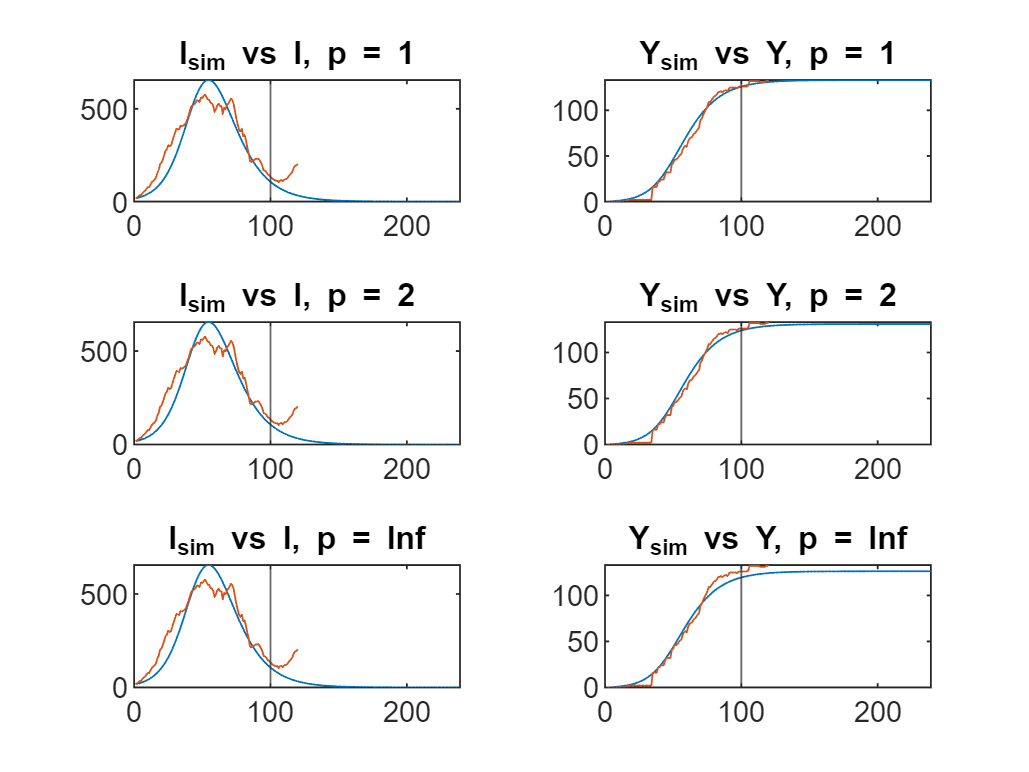

p = 1, predict first day below 5 infections after t0=52 is 151
p = 2, predict first day below 5 infections after t0=52 is 151


p = Inf, predict first day below 5 infections after t0=52 is 151


figure
tl = tiledlayout('flow');

for pInd = 1:pLen
    p = pSet(pInd);
    % Get minimum parameter values
    paramMin = paramMinp2(pInd,:);
    [alphaMin, betaMin, gammaMin, NMin] = paramMin{:};

    % Recalculated because it's not stored previously
    [Ssim, Isim, Rsim] = SIR_euler(I0, Tmax * 2, alphaMin, betaMin, NMin);

    % Compare Isim and I
    nexttile
    plot(Isim)
    hold on
    plot(I)
    xline(Tmaxnew)
    hold off
    %legend(["predicted", "actual"])
    title(['I_{sim} vs I, p = ', num2str(p)])

    % Compare Y and Ysim = gamma * Rsim
    nexttile
    plot(gammaMin * Rsim)
    hold on
    plot(Y(t0:t0+Tmax))
    xline(Tmaxnew)
    hold off
    %legend(["predicted", "actual"])
    title(['Y_{sim} vs Y, p = ', num2str(p)])    

    % Find value of Isim after index t0 below Vmin
    % TODO should I be looking at V instead? I don't know
    % how I would compare that with the output of the model...
    temp_mat = (Isim(t0+1:end)<=Vmin);
    %temp_mat(temp_mat == 0) = NaN;
    [~, min_idx] = max(temp_mat);

    fprintf("p = %d, predict first day below %d infections after t0=%d is %d\n", ...
        p, Vmin, t0, min_idx+t0)
    fprintf("")
end


fprintf("In reality, within the given data, I never goes below %d after t0=%d.\n", Vmin, t0)

In reality, within the given data, I never goes below 5 after t0=52.


## Question 3

% Get parameters
% Function defined in generateParams2.m
[~, ~, ~, ~, omega2] = generateParams2(alphaSet, R0Set, deltaSet, NfracSet, Nmax);

% gammas(alphaInd, betaInd, deltaInd, NInd, p) contains 
% gamma as calculated to minimize p-norm of residual
% of actual results as compared to euler model 
% with given parameters (alpha, beta, delta, N)
% J(...) contains the minimized function value
[J3, gammas3] = SEIR_euler_allParams(t0, Tmax, I0, Y, omega2, pSet);

Insufficient number of outputs from right hand side of equal sign to satisfy assignment.

Error in SEIR_euler_allParams (line 10)
    [alphaLen, betaLen, deltaLen, NLen, ~] = omegaLens{:};

% Save results (so if I need to restart I don't lose the calculations)
% Commented so that I don't overwrite the results later
%writematrix(J3,"project1_q3_errors_all_p.txt")
%writematrix(gammas3,"project1_q3_gammas_all_p.txt")

[~, ~, ~, paramMinp3] = SEIR_euler_minParams(omega2, pSet, J3, gammas3)

## Question 4

[J4, gammas4] = SEIR_euler_allParams(t0, Tmaxnew, I0, Y, I, omega2, pSet);

alphas iterated over: 0.05, 

Arrays have incompatible sizes for this operation.

Error in objectiveFunction (line 6)
    objFunc = norm(I-Isim, p) + lambda * norm(Y - gamma * Rsim, p);

Error in SEIR_euler_allParams (line 34)
                        minVal = objectiveFunction(Y,Rsim,I,Isim,gamma,1,p)

Related 

% Save results (so if I need to restart I don't lose the calculations)
% Commented so that I don't overwrite the results later
%writematrix(J4,"project1_q4_errors_all_p.txt")
%writematrix(gammas4,"project1_q4_gammas_all_p.txt")

% Load matrix from file above
J4 = readmatrix("project1_q4_errors_all_p.txt")
gammas4 = readmatrix("project1_q4_gammas_all_p.txt")

[~, ~, ~, ~, paramMinp4] = SEIR_euler_minParams(omega2, pSet, J4, gammas4)

figure
tl = tiledlayout('flow');

for pInd = 1:pLen
    p = pSet(pInd);
    % Get minimum parameter values
    paramMin = paramMinp4(pInd,:);
    [alphaMin, betaMin, gammaMin, deltaMin, NMin] = paramMin{:};

    % Recalculated because it's not stored previously
    [Ssim, Esim, Isim, Rsim] = SEIR_euler(I0, Tmax * 2, alphaMin, betaMin, deltaMin, NMin);

    % Compare Isim and I
    nexttile
    plot(Isim)
    hold on
    plot(I)
    hold off
    %legend(["predicted", "actual"])
    title(['I_{sim} vs I, p = ', num2str(p)])

    % Compare Y and Ysim = gamma * Rsim
    nexttile
    plot(gammaMin * Rsim)
    hold on
    plot(Y(t0:t0+Tmax))
    hold off
    %legend(["predicted", "actual"])
    title(['Y_{sim} vs Y, p = ', num2str(p)])    

    % Find value of Isim after index t0 below Vmin
    % TODO should I be looking at V instead? I don't know
    % how I would compare that with the output of the model...
    temp_mat = (Isim(t0+1:end)<=Vmin);
    %temp_mat(temp_mat == 0) = NaN;
    [~, min_idx] = max(temp_mat);

    fprintf("p = %d, predict first day below %d infections after t0=%d is %d\n", ...
        p, Vmin, t0, min_idx+t0)
    fprintf("")
end

fprintf("In reality, within the given data, I never goes below %d after t0=%d.\n", Vmin, t0)